## Reference Information

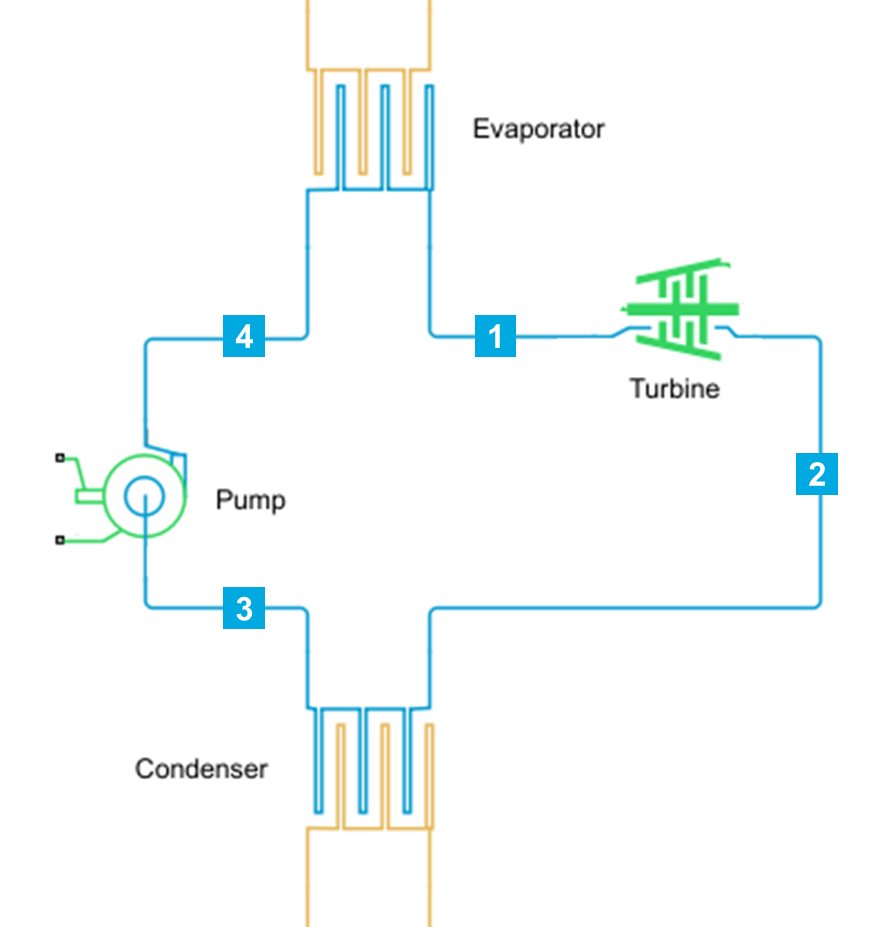  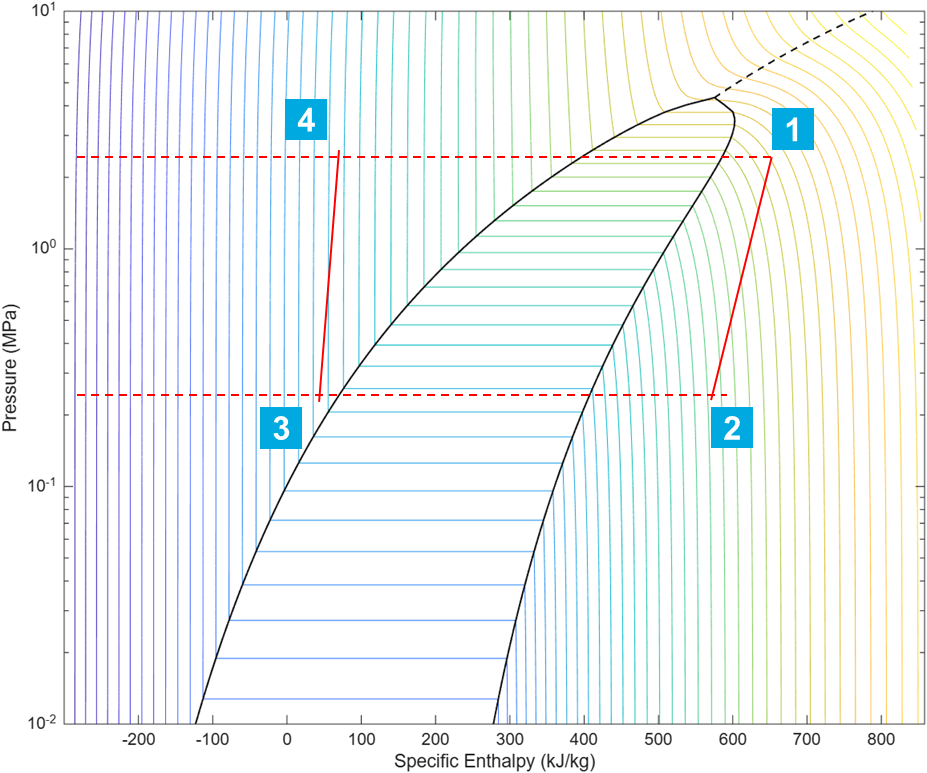

NominalStates = struct;

NominalStates.T = [300 240 132 145]; % degC
NominalStates.P = [2.3 0.23 0.23 2.3]; % MPa
NominalStates.H = [650.7 577.8 43.516 72.3]; % kJ/kg
NominalStates.mdot = 4.6;  % kg/s
NominalStates.Wout = 266.8; % kW
NominalStates.eta  = 0.1004; % 1

Evaporator = struct;
Evaporator.Oil   = struct;  % heating oil
Evaporator.Fluid = struct;  % working fluid, Toluene
Evaporator.Fluid.Tin  = NominalStates.T(4);
Evaporator.Fluid.Tout = NominalStates.T(1);
Evaporator.Fluid.mdot = NominalStates.mdot;
Evaporator.Oil.Tin  = 390;  % degC
Evaporator.Oil.Tout = 300;  % degC
Evaporator.Oil.mdot = 11.77;  % kg/s, estimated
Evaporator.Heat = NominalStates.mdot * (NominalStates.H(1) - NominalStates.H(4)); % kW

Condenser = struct;
Condenser.Water = struct;  % cooling water
Condenser.Fluid = struct;  % working fluid, Toluene
Condenser.Fluid.Tin  = NominalStates.T(2);
Condenser.Fluid.Tout = NominalStates.T(3);
Condenser.Fluid.mdot = NominalStates.mdot;
Condenser.Water.Tin  = 20;   % degC
Condenser.Water.Tout = 78.8; % degC
Condenser.Water.mdot = 10;   % kg/s
Condenser.Heat = NominalStates.mdot * (NominalStates.H(2) - NominalStates.H(3)); % kW

Pump = struct;
Pump.nom_capacity = 365; % lpm
Pump.max_capacity = Pump.nom_capacity * 1.25; % assumed
Pump.nom_head = (NominalStates.P(4)-NominalStates.P(3))*10^6/9.8*0.00132; % m
Pump.max_head = Pump.nom_head * 1.25; % assumed
Pump.nom_power = NominalStates.mdot * (NominalStates.H(4)-NominalStates.H(3));  % kW
Pump.nom_speed = 1000; % rpm, assumed

Turbine = struct;
Turbine.PR = NominalStates.P(1) / NominalStates.P(2);
Turbine.nom_mdot = NominalStates.mdot;
Turbine.P_ref = NominalStates.P(1);
Turbine.T_ref = NominalStates.T(1);
Turbine.eta_isen = 0.736; % isentropic eff., by trial & error.
Turbine.eta_mech = 0.841; % mechanical eff., estimated from reference power output and simulated fluid power.

## Save Data

save("Data\parameters.mat","Evaporator","Condenser","NominalStates","Pump","Turbine")